# **Lab 2: Echo Cancellation via Inverse Filtering**

This lab is adapted from Section 2.10, "Echo Cancellation via Inverse Filtering" in the course text *Computer Explorations in SIGNALS AND SYSTEMS*, 2nd edition, by Buck, Daniel, Singer.

In this set of exercises, you will consider the problem of removing an echo from a recording of a speech signal. 

**In the following set of tasks, enter and execute your code in the "Code"   sections, and answer the  underlined questions in in a "Text " section following your code section.**

**Task 1. Load echo_F23**`.mat`** and play  **`y`** with sampling rate Fs=22050.**

You should hear a voice signal with an echo. The signal $y[n]$, represented by vector `y`, is of the form

                    $\quad \quad \quad \quad y[n]=x[n]+\alpha x[n-N]$,

where $x[n]$ is the uncorrupted speech, which has been delayed by $N$ samples and added back in with its amplitude decreased by $\alpha < 1$. This is a reasonable model for an echo resulting from the signal off of an absorbing surface like a wall. If a microphone is placed in the center of a room, and a person is speaking at one end of the room, the recording will contain the speech which travels directly to the microphone, as well as an echo which traveled across the room, reflected off of the far wall, and then into the microphone. Since the echo must travel further, it will be delayed in time. Also, since the speech is partially absorbed by the wall, it will be decreased in amplitude. For simplicity, ignore any further reflections or other sources of echo.

load echo_F23.mat
Fs = 22050;
%sound(y, Fs);

**Task 2. An echo system - Impulse response of the echo system**

As discussed in task 1, the echo can be represented by a linear system of the form

                   $\quad \quad \quad \quad y[n]=x[n]+\alpha x[n-N]$.

In the above system, $x[n]$ is the input signal and $y[n]$ is the output signal. Use the echo time $N=5000$, and echo amplitude $\alpha = 0.9$.

 **Part 1.  **Find the impulse response of the above echo system (analytical solution ; hand-written or typed).

to find the impulse response given that alpha is 0.9 and N = 5000, we should do what we learned in 45 defines the impulse response:

y[n] = x[n] + alpa x[n- N] = x[n] * h[n]  --> we could recognize a shifted and scaled x being added or we could set x to be an impulse and get the response: (d stands for dirac here)

y[n] = d[n]*h[n] = d[n] + alpha d[n- N]   shows that h is holds x at n and also a shifted value of x at n- N (scaled by alpha) so h is:

h[n] = d[n] + 0.9 d[n - 5000]

**Part 2.  **Create a vector named  `h_echo `to store this impulse response for $0  \leq n \leq 5000$.

alpha = 0.9;
N = 5000;


h_echo = zeros(1, N+1)     % 0 vector

h_echo =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h_echo(1) = 1              % 1 at first position (n = 0)

h_echo =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h_echo(N+1) = alpha        % 1 at last position  (n = 5000)

h_echo =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**Part 3.  **Plot the impulse response (h_echo[n]).

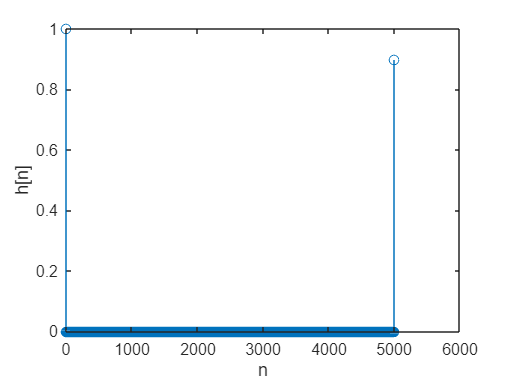

stem(h_echo)
xlabel('n')
ylabel('h[n]')

**Task 3. Echo removal by linear filtering - impulse response of the echo removal system - analytical solution**

Consider an echo removal system defined by the (recursive) difference equation

                               $y[n]+\alpha y[n-N] = x[n]$.

In the above system, $x[n]$ is the input signal and $y[n]$ is the output signal. This is an echo removal system, so the input signal, $x[n]$, is a signal that has an echo and the output, $y[n]$, is the signal which has the echo removed.  

**Part 1. **By setting $x[n]=v[n]+\alpha v[n-N]$, meaning that $x[n]$ is obtained by adding an echo to the signal $v[n]$, confirm that the original signal $v[n]$ equals the output $y[n]$of the echo removal system when $x[n]$ is the input. (That is, show that the echo signals produced by $v[n]$ and $y[n]$ are the same.)

x[n] = v[n] + av[n -N] , x[n] = y[n] + ay[n -N] --> y[n] + ay[n - N] = v[n] + av[n - N]   so y[n] = v[n]

**Part 2. ** Find the impulse response of the above echo removal system (analytical solution: hand-written or typed). 

The system here is the same as before except that it is now recursive so the signal is periodic or infinite by N. Since previously we just had a dirac and a scaled shifted dirac because of a absorbed echo, this described multiple echoes with stacked scaling:

h[n] = d[n] -  alpha d[n - N] + alpha^2 d[n -2N] .... (showing an echo at every period constructive then destructive)

**Part 3. ** Does this impulse response have a finite length or an infinite length?

Infinite length, since the new impulse repeats at every period, the length is infinite

**Task 4. Echo removal by linear filtering - impulse response of the echo removal system - MATLAB solution**

You will use the  `filter ` function in MATLAB to find the impulse response of the  echo removal system in task 3. The impulse response is the response of a system to the unit impulse signal. 

          $\quad \quad \quad \quad x[n]=\delta[n] \rightarrow y[n]=h[n]$.

(A tutorial on using the `filter` function can be found in Section 2.2 of the Computer Explorations textbook.)

**Part 1.  **To represent the input signal (unit impulse signal), create a vector named  `d `whose length is equal to 90001 such that the first entry is 1 and the remaining entries are 0. 

d = zeros(1, 90001)

d =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


d(1) = 1

d =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**Part 2. ** Use the `filter f`untion and input` d `to compute the impulse response of the echo removal system. Store the impulse response in a vector named` h_removal` . Plot the impulse response.

N = 5000;
alpha = 0.9;
b = 1;
a = [1, zeros(1, N-1), alpha]

a =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h_removal = filter(b, a, d)

h_removal =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


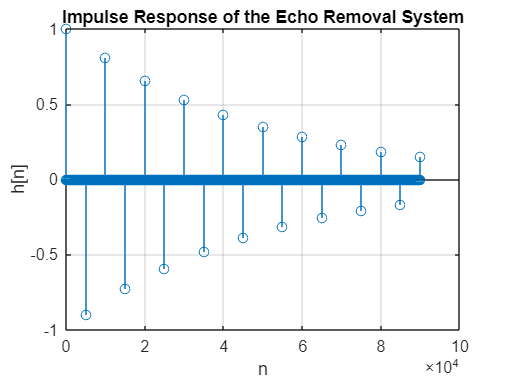

stem(h_removal);
xlabel('n');
ylabel('h[n]');
title('Impulse Response of the Echo Removal System');
grid on;

**Task 5. Echo removal by linear filtering - output of the echo removal system to a voice signal with an echo**

In this task you will use the `filter f`untion to find the output of the echo removal system in Task 3 when the input signal is vector y that you added to your workspace in Task 1. This input signal is a voice signal with an echo added to it. 

Use the `filter f`untion and vector `y` as the input signal to comput the output. Plot the output and play it with sampling frequency 22050. You should no longer hear the echo.

y_filt = filter(b, a, y)

y_filt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sound(y_filt, Fs)

**Task 6. Impulse response of the cascaded echo system and echo removal system.**

**Part 1.  **Find the overall impulse response of the cascaded echo system and the echo removal system, by convolving  `h_echo `and `h_removal.` Store the result in vector `h_overall `and plot it.

h_overall = conv(h_echo, h_removal)

h_overall =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


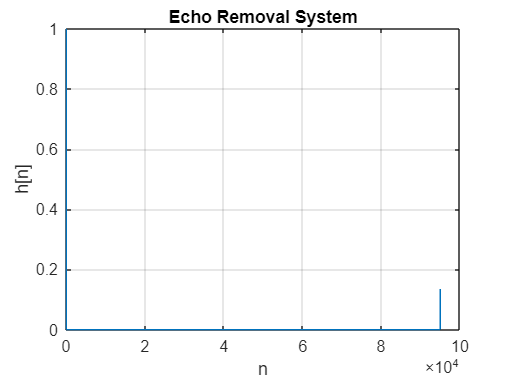

plot(h_overall)
xlabel('n');
ylabel('h[n]');
title('Echo Removal System');
grid on;

**Part 2.  **Given that the echo removal system is the inverse of the echo system, what type of signal would you** ideally** expect to receive as the result of convolving  `h_echo `and `h_removal`?  

`Since the convolving with the inverse should get the original signal, the impulse responses should ideally result in a dirac function or unit impulse. `

**Part 3. **By inspecting the plot of `h_overall,d`oes it represent a unit impulse? If it is not, explain the reason.

 No, the plot does not represent a unit impulse becuase the impulse response is infinite and MATLAB cannot fully model the infinite function so there is some truncation or approximation. 

**Part 4. **Confirm that `h_overall` does not represent the impulse response of the identity system by computing, playing, and plotting the output of the LTI system defined by `h_overall `when the input is the echo-free signal you found in Task 5.  Can you hear or see any effects of the deviation of h_overall from an ideal unit impulse? Describe them.

y_test = conv(h_overall, y_filt)

y_test =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


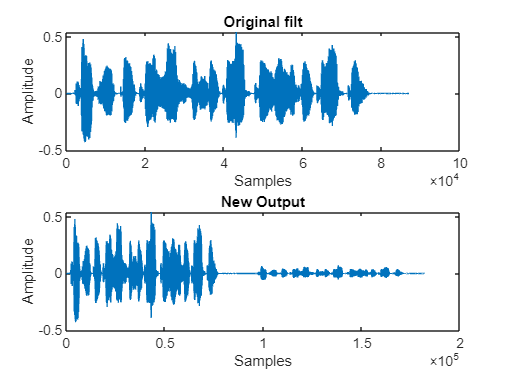

sound(y_filt, Fs)
pause(length(y_filt)/Fs + 1);
sound(y_test, Fs)
figure;
subplot(2,1,1);
plot(y_filt);
title('Original filt');
xlabel('Samples');
ylabel('Amplitude');

subplot(2,1,2);
plot(y_test);
title('New Output');
xlabel('Samples');
ylabel('Amplitude');


%The sound was a little harder to hear but the plots show the signal is
%quite similar but now with an extra reverb after the signal, this part
%makes sense when looking at the "Echo Removal System" graph that shows
%another impulse at around n = 90000

**Task 7. Estimation of echo delay and magnitude from the autocorrelation function.**

Suppose that you were given $y[n]$ but did not know the value of the echo time, $N$, or the amplitude of the echo, $\alpha$. Here we describe a method that can sometimes be used to estimate these values.  Rewrite the echo system difference equation in the form     

                  
$$\quad \quad \quad \quad y[n]=x[n] \ast (\delta[n] + \alpha \delta[n-N])$$
 

consider the signal 

               
$$\quad \quad \quad \quad R_{yy}[n] = y[n] \ast y[-n].$$


This is called the autocorrelation fucntion of the signal $y[n]$ and is often used in applications of echo-time esitmation.

**Part 1. **Write a formula  for $R_{yy}[n]$ in terms of $R_{xx}[n]$.

 R_yy[n] is given by the convolution of the shifted (R_xx) function so it would result in: 

    R_xx[n] + aR_xx[n - N] + aR[n + N] + a^2R_xx[n]  (flip and drag)

**Part 2. **Plot the autorcorrelation function of the echo signal $R_{yy}[n]$.

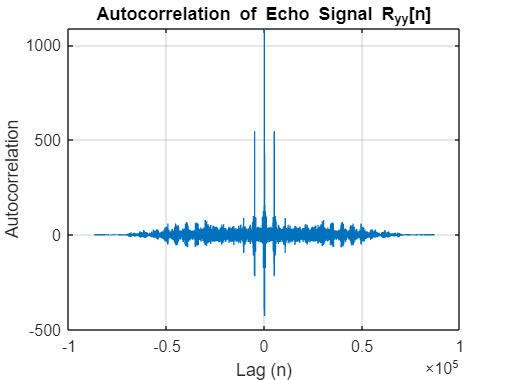

Ryy = xcorr(y, y); 
n = -floor(length(Ryy)/2) : floor(length(Ryy)/2) ; % Time shifts
figure;
plot(n, Ryy);
xlabel('Lag (n)');
ylabel('Autocorrelation');
title('Autocorrelation of Echo Signal R_{yy}[n]');
grid on;

**Part 3. **Plot the autorcorrelation of the recovered voice signal $R_{xx}[n]$.

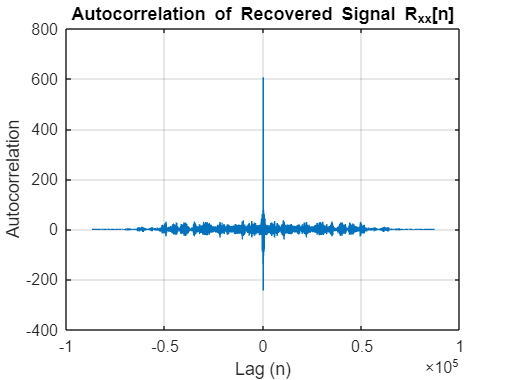

Rxx = xcorr(y_filt, y_filt);
figure;
plot(n, Rxx);
xlabel('Lag (n)');
ylabel('Autocorrelation');
title('Autocorrelation of Recovered Signal R_{xx}[n]');
grid on;

 **Part 4.** Referrring to your results in Parts 1 and 2, how would you estimate $N$ and $\alpha$ from the plot in Part 2? Can you always get  accurate estimates for these parameters from the autocorrelation function?

To estimate N (given as a period), we could find secondary peaks of R_yy becuase that is where the residual echo is (not at full strength). Next to find alpha, the ratio of the strength of the first to the second you could simply divide the height of the secondary peak by the height of the primary peak, but the primary peak from the Rxx signal because Ryy also includes the a^2 scaled primary peak. You can't always get accurate estimates for the same reason as previous however, the estimates in this case should be fairly close to the actual parameters. The accuracy also depends on the autocorrelation of the orignal signal in this case we see that there is a quite large disparity from n = 0 to the rest of n, but if there wasn't then the estimates would likely be much less accurate. 